%% 铝的材料属性
CL = 6.176; % 纵波波速(mm/μs)
CT = 3.103; % 横波波速(mm/μs)
mu = 26; % (MPa)
lambda = 51; % (MPa)
rho = 2.7; % 密度(g/mm3)

%% 几何属性
d = 1; % 板厚(mm)
h = d/2;

fd = 1.5

fd =    1.500000000000000


% fd = 1; % 厚频率(MHz·mm)
f = fd/d; % 频率(MHz)
w = f*2*pi; % 圆频率(MHz)
w_sca = w*h/CT; % 无量纲化频率

# 波结构

#### 对称模式


$$\left\lbrace \begin{array}{l}
\Phi =A_2 \cos \left({px}_2 \right)\\
\psi =B_1 \sin \left({qx}_2 \right)\\
u={ikA}_2 \cos \left({px}_2 \right)+{qB}_1 \cos \left({qx}_{2\;} \right)\\
v=-{pA}_2 \sin \left({px}_2 \right)-{ikB}_1 \sin \left({qx}_2 \right)\\
\sigma_{21} =\mu \left\lbrack -2ikp\;\sin \left({px}_2 \right)A_2 +\left(k^2 -q^2 \right)\;\sin \left({qx}_2 \right)B_1 \right\rbrack \\
\sigma_{22} =-\lambda \left(k^2 +p^2 \right)\cos \left({px}_2 \right)A_2 -2\mu \left\lbrack p^2 \;\cos \left({px}_2 \right)A_2 +ikqcos\left({qx}_2 \right)B_1 \right\rbrack 
\end{array}\right.$$


边界条件


$$\left\lbrack \begin{array}{cc}
-2\mu \mathrm{ikp}\;\sin \left(ph\right) & \mu \left(k^2 -q^2 \right)\sin \left(qh\right)\\
-\mu \left(q^2 -k^2 \right)\cos \left(ph\right) & -2\mu \mathrm{ikq}\;\cos \left(qh\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
A_2 \\
B_1 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


%% 求解频散方程
Fun = @lamb_sym; % 求解实波数
[Kd,Wd,t] =  get_wavenumber(w_sca,Fun);

% 量纲还原
K = Kd/h;
W = Wd*CT/h;

P = sqrt(W.^2/CL^2 - K.^2);
Q = sqrt(W.^2/CT^2 - K.^2);
V = cell(t,1);
D = cell(t,1);

for it = 1:t
	k = K(it);
	p = P(it);
	q = Q(it);
	M(1,1) = mu*(-2i*k*p*sin(p*h));
	M(1,2) = mu*((k^2-q^2)*sin(q*h));
	M(2,1) = -mu*((q^2-k^2)*cos(p*h));
	M(2,2) = -2*mu*1i*k*q*cos(q*h);
	[V{it},D{it}] = eig(M);
% 	det(M)
% 	abs(det(D{1}))
end

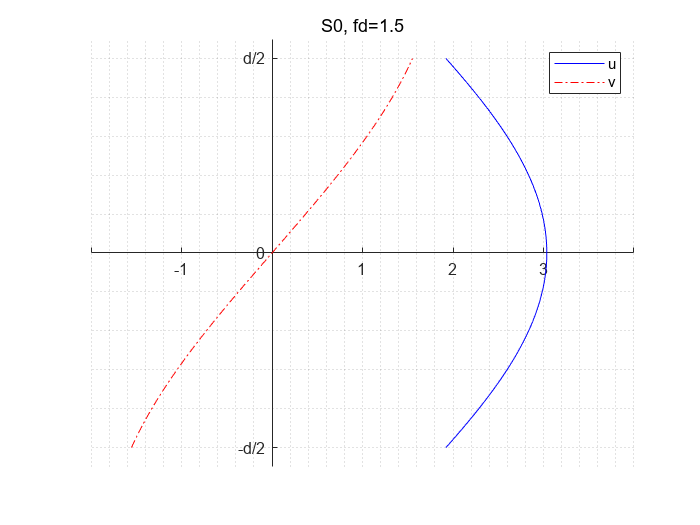

n = 1; % 一阶模态
k = K(n); p = P(n); q = Q(n); A = V{n};

x = linspace(-h,h,100)';

u = [1i*k*cos(p*x),  q*cos(q*x)] * A(:,2);
v = [-p*sin(p*x), -1i*k*sin(q*x)] * A(:,1);

figure
hold on
plot(real(u),x,'b-'); plot(real(v),x,'r-.');
% plot(zeros(size(x)),x,'k','LineStyle',':') % 辅助直线
hold off

ax1 = gca;
set(ax1,'XAxisLocation','origin','YAxisLocation','origin','YTick',[-h,0,h], ...
	'yticklabels',{'-d/2','0','d/2'},'YLim',[-1.1*h,1.1*h])
title(['S',num2str(n-1),', fd=' num2str(2*f*h)]); 
legend('u','v'); grid minor

#### 反对称模式


$$\left\lbrace \begin{array}{l}
\Phi =A_1 \sin \left({px}_2 \right)\\
\psi =B_2 \cos \left({qx}_2 \right)\\
u={ikA}_1 \sin \left({px}_2 \right)-{qB}_2 \sin \left({qx}_{2\;} \right)\\
v={pA}_1 \cos \left({px}_2 \right)-{ikB}_2 \cos \left({qx}_2 \right)\\
\sigma_{21} =\mu \left\lbrack 2ikp\;\cos \left({px}_2 \right)A_1 +\left(k^2 -q^2 \right)\;\cos \left({qx}_2 \right)B_2 \right\rbrack \\
\sigma_{22} =-\lambda \left(k^2 +p^2 \right)\sin \left({px}_2 \right)A_1 -2\mu \left\lbrack p^2 \;\sin \left({px}_2 \right)A_1 -ikq\;\sin \left({qx}_2 \right)B_2 \right\rbrack 
\end{array}\right.$$


边界条件


$$\left\lbrack \begin{array}{cc}
2\mathrm{i}\mu \mathrm{kp}\;\cos \left(ph\right) & \mu \left(k^2 -q^2 \right)\;\cos \left(qh\right)\\
-\mu \left(q^2 -k^2 \right)\sin \left(ph\right) & 2\mathrm{i}\mu \mathrm{kq}\;\sin \left(qh\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
A_1 \\
B_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


%% 求解频散方程
Fun = @lamb_asy; % 求解实波数
[Kd,Wd,t] =  get_wavenumber(w_sca,Fun);

% 量纲还原
K = Kd/h;
W = Wd*CT/h;

P = sqrt(W.^2/CL^2 - K.^2);
Q = sqrt(W.^2/CT^2 - K.^2);
V = cell(t,1);
D = cell(t,1);

for it = 1:t
	k = K(it);
	p = P(it);
	q = Q(it);
	M(1,1) = mu*(2i*k*p*cos(p*h));
	M(1,2) = mu*((k^2-q^2)*cos(q*h));
	M(2,1) = -mu*((q^2-k^2)*sin(p*h));
	M(2,2) = 2*mu*1i*k*q*sin(q*h);
	[V{it},D{it}] = eig(M);
% 	det(M)
% 	abs(det(D{1}))
end

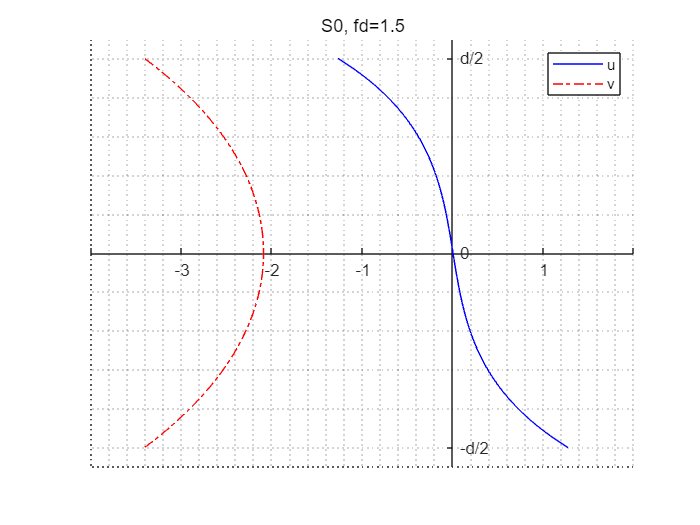

n = 1; % 一阶模态
k = K(n); p = P(n); q = Q(n); A = V{n};

x = linspace(-h,h,100)';

u = [1i*k*sin(p*x),  -q*sin(q*x)] * A(:,2);
v = [p*cos(p*x), -1i*k*cos(q*x)] * A(:,1);

figure
hold on
plot(real(u),x,'b-'); plot(real(v),x,'r-.');
% plot(zeros(size(x)),x,'k','LineStyle',':') % 辅助直线
hold off

ax1 = gca;
set(ax1,'XAxisLocation','origin','YAxisLocation','origin','YTick',[-h,0,h], ...
	'yticklabels',{'-d/2','0','d/2'},'YLim',[-1.1*h,1.1*h])
title(['S',num2str(n-1),', fd=' num2str(2*f*h)]);
legend('u','v'); grid minor